# **整体优化**

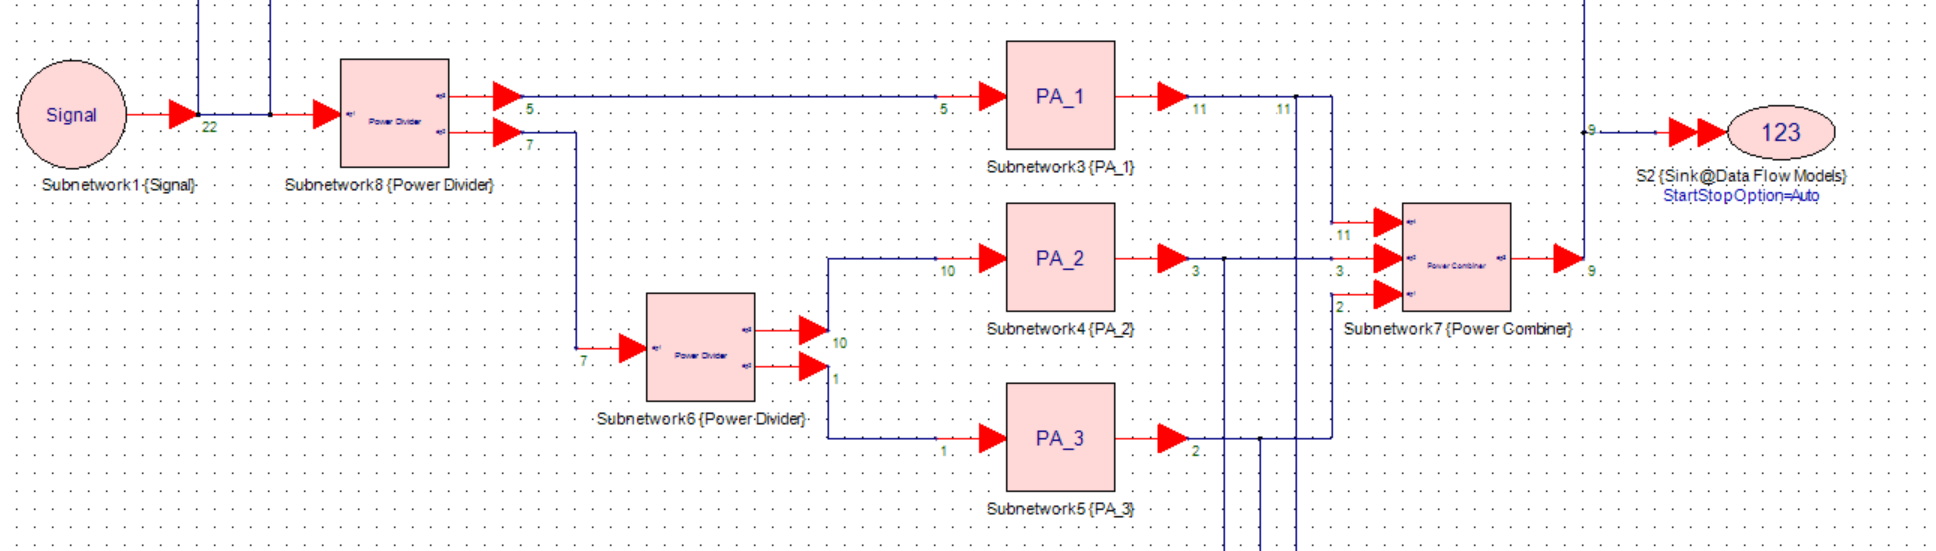

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Model A Train----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Sys_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 
% 参数需要保持一致
M = 4; 

## 【训练】整体训练

% 训练整体
model=Train_FNN(M,dim,Sys_input,Sys_output,5);
save('Method_A\Whole\FNN.mat', 'model');

## Model Test

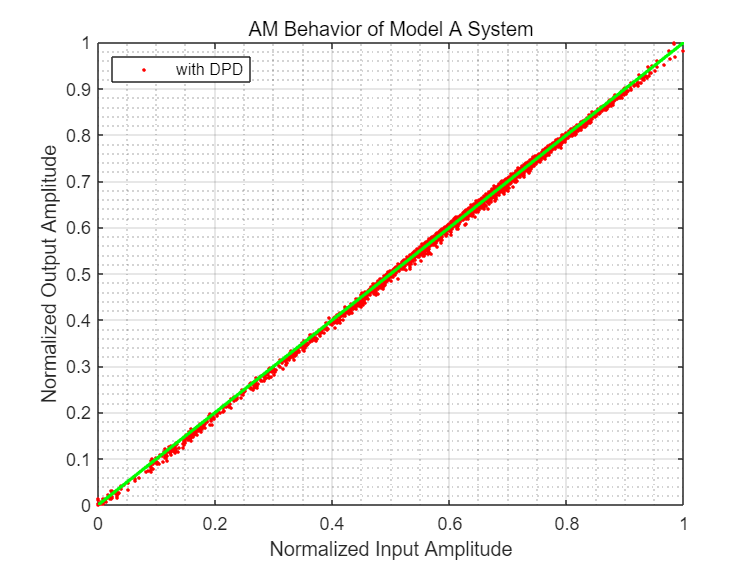

% 模型仿真
Sys_input_DPD=DPD(Sys_input,M,'Method_A\Whole\FNN.mat');
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_output = PA_1(A1_input);
A2_output = PA_2(A2_input);
A3_output = PA_3(A3_input);
Sys_output_sim = Power_Combiner(A1_output,A2_output,A3_output);
% 性能评估
Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Model A System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model A，系统的NMSE(Train)仿真结果为 %f dB\n', nmse_sim);

使用Model A，系统的NMSE(Train)仿真结果为 -34.991971 dB


## -----------------------------Model A Valid----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Valid();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
% 参数需要保持一致
M = 4;

## Model Test

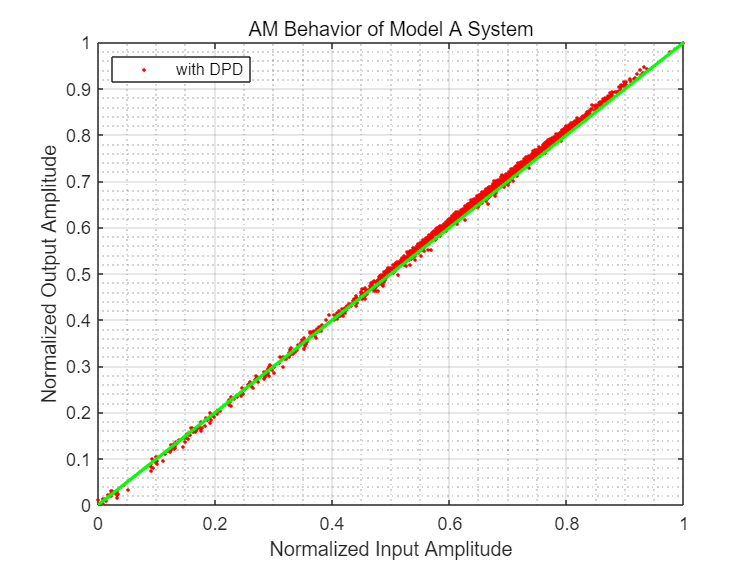

% 模型仿真
Sys_input_DPD=DPD(Sys_input,M,'Method_A\Whole\FNN.mat');
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_output = PA_1(A1_input);
A2_output = PA_2(A2_input);
A3_output = PA_3(A3_input);
Sys_output_sim = Power_Combiner(A1_output,A2_output,A3_output);
% 由于PA和DPD的延时，所以少算（4+M）个值
Sys_input = Sys_input(5+M:end);
Sys_output_sim = Sys_output_sim(5+M:end);
% 性能评估
Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Model A System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model A，系统的NMSE(Valid)仿真结果为 %f dB\n', nmse_sim);

使用Model A，系统的NMSE(Valid)仿真结果为 -32.463221 dB
